% This test file allows to test the segmenting fuction in 4 different data samples
% use variable n_test to chose the data sample

clear all

load('test')


% SELECT TEST
% 1 = 3min flow recording adult using biopac pnemograph supine sampling freq 500Hz
% 2 = 1min flow recording infant sedated pnemograph supine sampling frew 500Hz
% 3 = 15 min flow recording children NREM impedance pnemograpy supine sampling frew 256Hz 
% 4 = 4.5 min flow recording children REM impedance pnemograpy supine sampling frew 256Hz

n_test = 2;

disp(test_signals{n_test}.description)

1min flow recording infant sedated pnemograph supine sampling frew 500Hz 


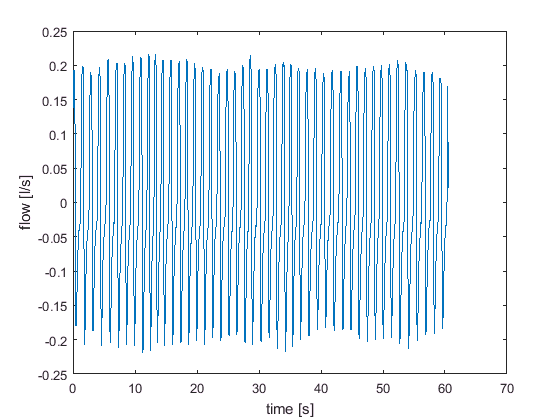

flow = test_signals{n_test}.flow;
flow_units = test_signals{n_test}.flow_units;
fs = test_signals{n_test}.fs;
time = linspace(0,(length(flow)-1)/fs,length(flow))';
volume = cumsum(flow)./fs;

    
%Plot chosen signal
plot(time,flow)
xlabel('time [s]')
ylabel(['flow [' flow_units ']'])

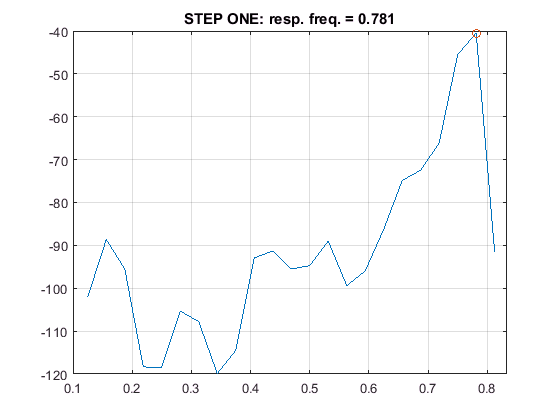

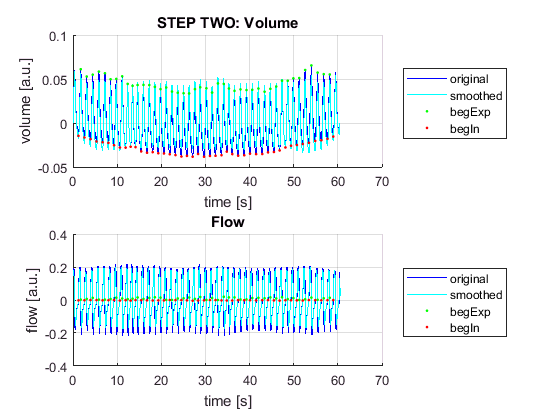

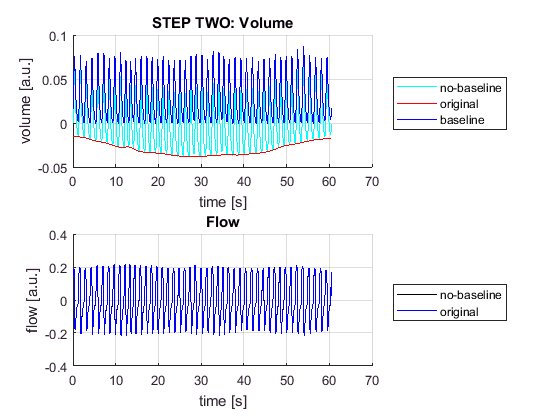

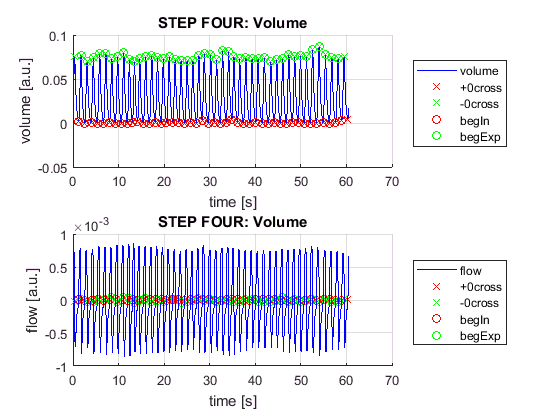

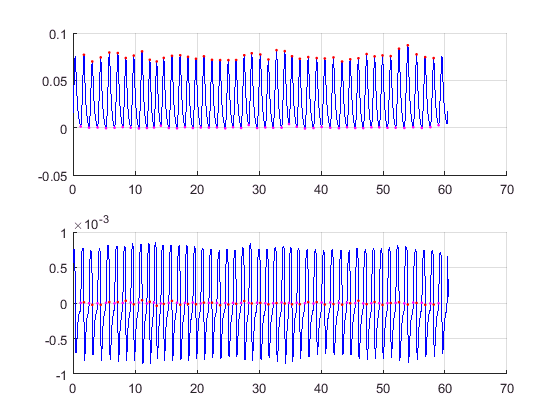




[seg,volume,Vdrift] = cyclesAdvance(fs, volume, [], 'plotDetails' );